% Example 3.4 from Murray Lectures 
% solved using symbolic tools% State equations
syms x1 x2 p1 p2 u;
Dx1 = x2;
Dx2 = u;

% Properties of dynamical system
A = [0 1; 0 0];
B = [0;1];
[n,~] = size(A);

% Penaliza
q = 2;
Qx = [q^2 0; 0 0];
Qu = 1;

% Argumento del funcional
L = [x1,x2]*Qx*[x1;x2] + Qu*u^2;

% Montar el Hamiltoniano
H = L + p1*Dx1 + p2*Dx2;

% Costate equations
Dp1 = -diff(H,x1);
Dp2 = -diff(H,x2);

% solve for control u
du = diff(H,u);
sol_u = solve(du, u);

% Substitute u to state equations
Dx2 = subs(Dx2, u, sol_u);

% convert symbolic objects to strings for using ’dsolve’
eq1 = strcat("Dx1=",char(Dx1));
eq2 = strcat("Dx2=",char(Dx2));
eq3 = strcat("Dp1=",char(Dp1));
eq4 = strcat("Dp2=",char(Dp2));

% case a: (a) x1(0)=-1 x2(0)=1; x1(2) = 0; x2(2) = 0;
conA1 = "x1(0) = -1";
conA2 = "x2(0) = 1";
conA3 = "x1(2) = 0";
conA4 = "x2(2) = 0";
sol_a = dsolve(eq1,eq2,eq3,eq4,conA1,conA2,conA3,conA4);

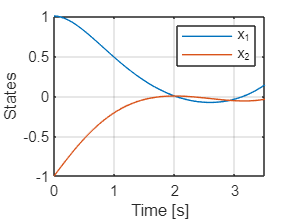

figure(1)
fplot(sol_a.x2,[0, 3.5], "DisplayName","x_1");
hold on;
fplot(sol_a.x1,[0, 3.5], "DisplayName","x_2");
grid on
xlabel("Time [s]")
ylabel("States")
legend()
hold off